# Linear Mixed Models - Part II

Linear mixed models are a powerful statistical analysis method To estimate relAtionships between the outcome measures and the independent variables of an experiment.

Although the LMM always returns a result, that result is based on some important assumptions. First is that the residuals are normally distributed, second that the variance is the same in all conditions. In part I you saw some code that helps you assess whether the assumptions are met. In this part we'll look at some strategies to build a better model when there are clear deviations from normality or homoscedasticity. 

## Solution 1 - Add predictors

It is important to realize that residuals are a combination of true measurement noise plus any dependencies in the data that the model cannot capture. You cannot change the measurement noise, but you can try to extend the model to capture the data better. 

For instance, in these simulated data we measure subject performance on some task after receiving three doses of a performance enhancing drug:

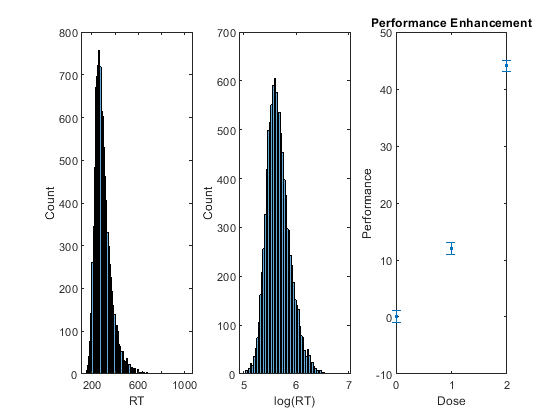

rng(1234,'twister'); % Fix RNG
dose = [0 1 2];
nrDoses = numel(dose);
meanPerformance = 2*dose+10*dose.^2;
nrSubjects=  100;
performance = repmat(meanPerformance,[nrSubjects 1])+randn([nrSubjects nrDoses]); % Add measurement noise
allDose = repmat(dose,[nrSubjects 1]);
subject = repmat((1:nrSubjects),[1 nrDoses]);
T =table(performance(:),subject(:),allDose(:),'VariableNames',{'performance','subject','dose'});
summary = groupsummary(T,'dose',{'mean','std'},'performance');
errorbar(summary.dose,summary.mean_performance,summary.std_performance,'.')
xlabel 'Dose'
ylabel 'Performance'
title 'Performance Enhancement'

A linear mixed model shows a significant effect of dose:

lmm = fitlme(T,'performance~dose')

lmm = Linear mixed-effects model fit by ML

Model information:
    Number of observations             300
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    performance ~ 1 + dose

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1802.5    1813.6    -898.26          1796.5  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF     pValue         Lower      Upper  
    {'(Intercept)'}        -3.2585      0.4411    -7.3873    298      1.515e-12    -4.1266    -2.3905
    {'dose'       }         21.993     0.34168     64.369    298    7.2175e-177     21.321     22.666

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}        4.832       4.4605   

But inspection of the residuals shows that the assumption of normal residuals is invalid. We easily see this graphically:

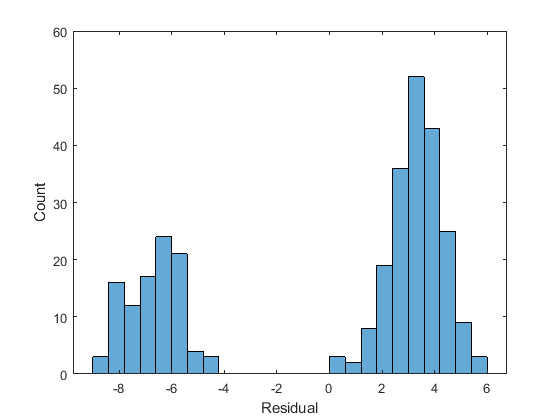

R = residuals(lmm);
figure;
nrBins = 25;
histogram(R,nrBins)
xlabel 'Residual'
ylabel 'Count'

Clearly this is not a normal distribution. Let's look at the model fit to see what happend

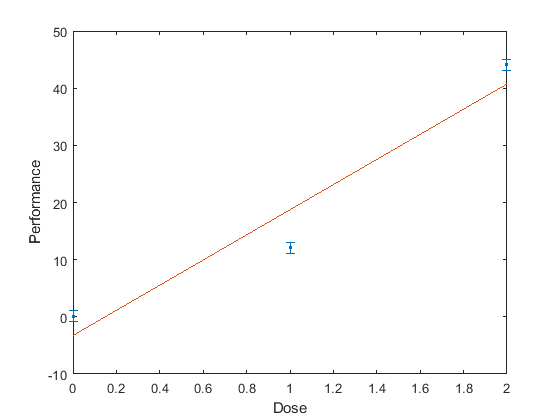

figure;
errorbar(summary.dose,summary.mean_performance,summary.std_performance,'.')
hold on
% Use linear algebra to make model-based predictions.
x = [ones([1 nrDoses]);dose];
y = lmm.fixedEffects'*x;
plot(dose,y)
xlabel 'Dose'
ylabel 'Performance'

Apparently that is the best linear model, but clearly the model misses an entire dose level, which results in that second mode in the residual distribution. We can fix this by adding more complexity to the model:

lmm = fitlme(T,'performance~dose+dose^2') % Add a squared dependence on dose

lmm = Linear mixed-effects model fit by ML

Model information:
    Number of observations             300
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    performance ~ 1 + dose + dose^2

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    856.15    870.97    -424.08          848.15  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF     pValue         Lower       Upper 
    {'(Intercept)'}        0.085056    0.099466    0.85512    297        0.39318    -0.11069    0.2808
    {'dose'       }          1.9317     0.25359     7.6174    297     3.4865e-13      1.4326    2.4308
    {'dose^2'     }          10.031     0.12182      82.34    297    1.5033e-206       9.791    10.271

Random effects covariance parameters (95% CIs):

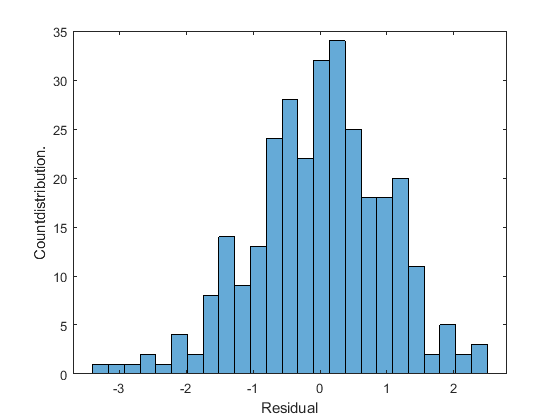

R = residuals(lmm);
figure;
histogram(R,nrBins)
xlabel 'Residual'
ylabel 'Count'distribution. 

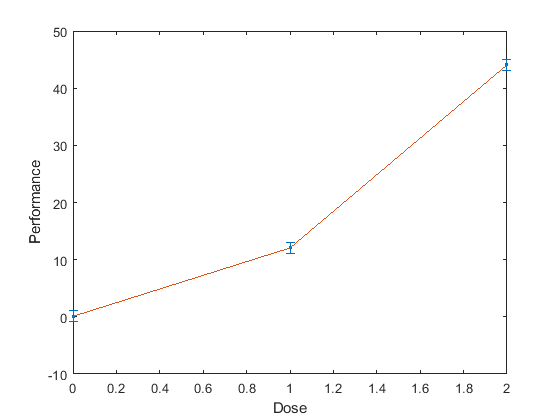

figure;
errorbar(summary.dose,summary.mean_performance,summary.std_performance,'.')
hold on
x = [ones([1 nrDoses]);dose;dose.^2];
y = lmm.fixedEffects'*x;
plot(dose,y)
xlabel 'Dose'
ylabel 'Performance'

And we can also test this more formally, and show the residuals as a function of the dose.

fullT = addvars(T,R,'NewVariableNames','residual'); % Add R to the table
groupsummary(fullT,'dose','std','residual') % Show std of residualrs

ans = 3×3 table
    dose    GroupCount    std_residual
    ____    __________    ____________

     0         100          0.98607   
     1         100           1.0016   
     2         100           1.0112   


% Test normality
normal = makedist('norm','mu',0,'sigma',nanstd(R));
[notNormal,p] = kstest(R,'cdf',normal)

notNormal = logical
   0


p = 0.7843

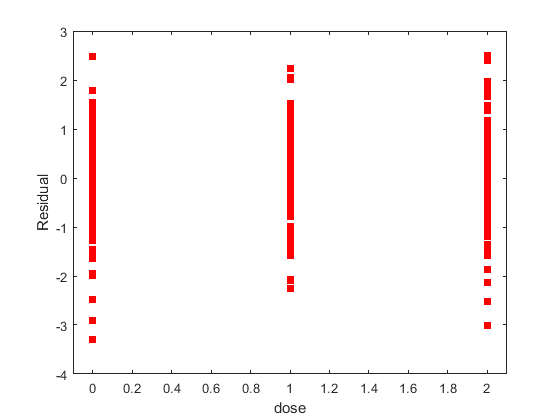

figure;
gscatter(T.dose,R)
xlabel 'dose'
ylabel 'Residual'

So the lesson learned is that you should always visualize the residuals, visualize the model together with the data, and, if necessary, add complexity to the model (i.e. add fixed or random effects) to improve the fit. In real life you won't know for sure which effects to add, and knowing what to add is more complicated in models that already have numerous fixed effects. That said, if your data show an increasing change of the dependent variable with some independent variable, then try adding a quadratic fixed effect of that independent variable (as we did here). 

Note that the goal here should not just be to get normal, and homoscedastic residuals; you are **estimating** model parameters after all and these are more meaningful than the p-value of each effect. Knowing whether there is a linear, or quadratic dependence on an independent variable can help understand the underlying mechanisms or inform practical applications. For instance, if a patient is not responsive to a drug at dose X, and you want to decide which higher dose to try, it is important to know whether the effect of dose is typically linear ( a large increase in dose may be needed) or quadratic (a small increase in dose may be enough). 

## Solution 2 -  Transform independent variables 

Quite often, an outcome depends on an experimental, independent variable, but the influence gets smaller with higher levels of the independent variable. An example is the mean firing rate following a sensory stimulus of a given strength (e.g. contrast in the visual system, sound level in the auditory system). The neural activity first increases with the sensory input level, but then saturates. 

rng(1234,'twister')
input  = 0.1:0.1:1;
nrInputs = numel(input);
response = log(input)-log(0.1);
nrNeurons = 100;
measurement = repmat(response,[nrNeurons 1]) + 0.25*randn([nrNeurons nrInputs]);
allInput  =repmat(input,[nrNeurons 1]);

T = table(measurement(:),allInput(:),'VariableNames',{'response','input'});
summary = groupsummary(T,'input',{'mean','std'},'response');
figure;clf
errorbar(summary.input,summary.mean_response,summary.std_response);
xlabel 'Input'
ylabel 'Mean Response'
title 'A saturating response'

We naively ignore the saturation, and fit a linear model:

lmm = fitlme(T,'response~input')

lmm = Linear mixed-effects model fit by ML

Model information:
    Number of observations            1000
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    response ~ 1 + input

Model fit statistics:
    AIC       BIC      LogLikelihood    Deviance
    649.98    664.7    -321.99          643.98  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF     pValue        Lower      Upper  
    {'(Intercept)'}        0.25812     0.022809    11.317    998    5.0829e-28    0.21336    0.30288
    {'input'      }         2.2826      0.03676    62.095    998             0     2.2105     2.3547

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower      Upper  
    {'Res Std'}        0.33389     0.31957    0.3

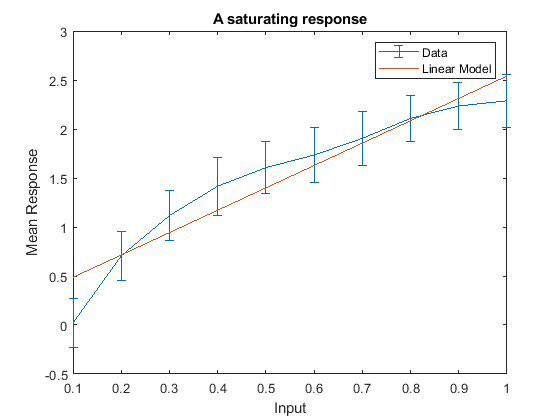

x = [ones([1 nrInputs]);input];
y = lmm.fixedEffects'*x;
hold on;
plot(input,y)
legend ('Data','Linear Model')

Even though the fit is reasonably close to the mean values, there is obviously something missing. The residuals show this even more clearly:

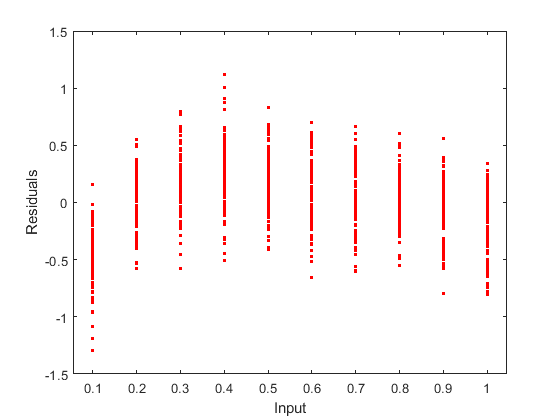

R=residuals(lmm);
figure;
gscatter(T.input,R)
xlabel 'Input'
ylabel 'Residuals'

There is a systematic mismatch; extereme input values have, on average, negative residuals, while the middle range has positive mean residuals. That suggests, again, that something is missing in the model. Of course in these simulated data we know that it is the `log` that is missing, but often a log transform will handle saturation effects quite well. 

The Wilkinson formula does not know how to handle functions (e.g. `'response ~log(input)'` will not work as an input to `fitlme`) , but we can simply add a column to the table that stores the log and then re-fit the model using that column:

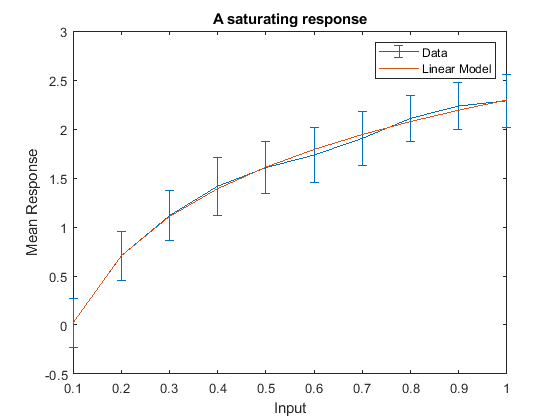

T = addvars(T,log(T.input),'NewVariableNames','logInput');
lmm = fitlme(T,'response~logInput');
x = [ones([1 nrInputs]);log(input)];
y = lmm.fixedEffects'*x;
figure;clf
errorbar(summary.input,summary.mean_response,summary.std_response);
xlabel 'Input'
ylabel 'Mean Response'
title 'A saturating response'
hold on;
plot(input,y)
legend ('Data','Linear Model')

For estimation purposes it is critical to realize that the fixed effects in the model now represent how much the mean response increase with each unit increase in the log of the input. Whether this is a reasonable thing to do, depends on your data. You make the choice based on a combination of a-priori knowledge  ("firing rates typically saturate") , visualization of your data ("the response curve seems to saturate") , and you can supplement this with formal model comparisons :

linearModel = fitlme(T,'response~input');
logModel = fitlme(T,'response~logInput');
compare(logModel,linearModel)

ans =     Theoretical Likelihood Ratio Test

    Model          DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue
    logModel       3     169.82    184.55    -81.911                                
    linearModel    3     649.98     664.7    -321.99    -480.16    0          0     


As the name suggests, the compare function compares two models and allows you to select the best one, based on AIC/BIC measures. In this case, the AIC for the `logModel` is, not surprisingly, much lower; that provides further insight that the log-model really is the better one.

## Solution 3 - Transform the dependent variable

In some cases, it is not the raw measurement, but some transformation of the raw measurement that depends linearly on the independent variable. A well-known example in behavioral neuroscience is the reaction time. Reaction times cannot be negative so almost by definition, a linear model cannot have truly normal residuals. Several researchers have noted that the distribution of a large sample of reaction times often has a long tail. 

A function that captures empirical RT distributions really well is the Ex-Gaussian, it is a combination of a Gaussian distribution with an exponential tail:


$$p(rt) =0.5* \frac{1}{\tau}*\exp(\frac{\mu}{\tau} +\frac{\sigma^2}{2*\tau^2} -\frac{rt}{\tau})*(1+erf(\frac{1}{\sqrt2}*\frac{rt-\mu-\sigma^2/\tau}{\sigma}))$$


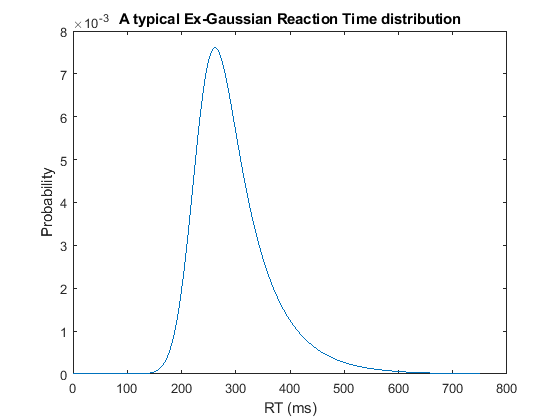

mu = 230;
sigma = 30;
tau = 65;
rt = 0:750;
figure;
plot(rt,exgaussianpdf(rt,mu,sigma,tau))
xlabel 'RT (ms)'
ylabel 'Probability'
title 'A typical Ex-Gaussian Reaction Time distribution'

Let's see how this affects LMM analyses. Let's  say you are investigating whether TMS applied to prefrontal cortex improves reaction time on a decision making task. We'll simulate that the actual effect is that RT decreases by 20 ms on average.

rng(12345,'twister'); 
TMSEFFECT = 20;
nrSubjects = 150;
shamRT = randexg([nrSubjects 1],mu,sigma,tau); % Generate random numbers from the Ex-Gaussian distribution
stimRT = randexg([nrSubjects 1],mu-TMSEFFECT,sigma,tau);
hasTMS = [false(nrSubjects,1);true(nrSubjects,1)];
T= table([shamRT;stimRT],hasTMS, 'VariableNames',{'rt','TMS'});
lmm = fitlme(T,'rt~TMS')

lmm = Linear mixed-effects model fit by ML

Model information:
    Number of observations             300
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    rt ~ 1 + TMS

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3403.3    3414.4    -1698.7          3397.3  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat      DF     pValue         Lower      Upper  
    {'(Intercept)'}         299.18     5.6856     52.621    298    6.6964e-153     287.99     310.37
    {'TMS_1'      }        -26.393     8.0407    -3.2824    298      0.0011517    -42.217    -10.569

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower    Upper 
    {'Res Std'}        69.635      64.28    75.435


Now let's look at the residuals:

R =residuals(lmm);
normal = makedist('norm','mu',0,'sigma',nanstd(R));
[notNormal,p] = kstest(R,'cdf',normal)

notNormal = logical
   1


p = 0.0148

Noting the skew in the typical RT distribution, and the non-normality of the residuals in linear models, researchers often transform RT data to get a derived measure that is more normally distributed. Some use log(RT), other 1./RT

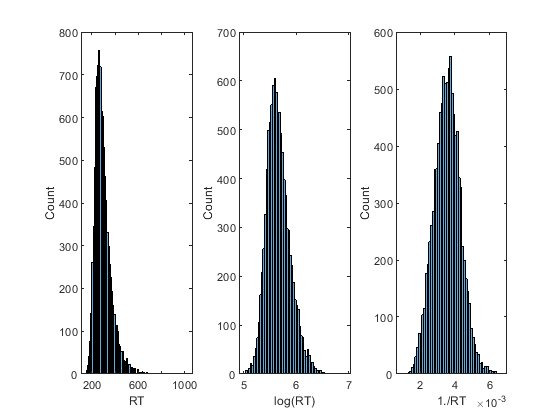

rtDistribution = randexg([10000 1],mu,sigma,tau);
figure;
subplot(1,3,1)
histogram(rtDistribution)
xlabel 'RT'
ylabel 'Count'
subplot(1,3,2)
histogram(log(rtDistribution))
xlabel 'log(RT)'
ylabel 'Count'
subplot(1,3,3)
histogram(1./rtDistribution)
xlabel '1./RT'
ylabel 'Count'

It is clear that the log(RT) and 1./RT are more symmetric, and closer to a Gaussian. Based on this we can try to use these transformed measures in the linear model:

T = addvars(T,log(T.rt),'NewVariableNames','logRT');
lmmLog = fitlme(T,'logRT~TMS')

lmmLog = Linear mixed-effects model fit by ML

Model information:
    Number of observations             300
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    logRT ~ 1 + TMS

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -28.548    -17.436    17.274           -34.548 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF     pValue        Lower       Upper   
    {'(Intercept)'}         5.6788     0.018651     304.47    298             0      5.6421      5.7155
    {'TMS_1'      }        -0.1016     0.026377    -3.8518    298    0.00014358    -0.15351    -0.04969

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower      Upper  
    {'Res Std'}        0.22843     0

R =residuals(lmmLog);
normal = makedist('norm','mu',0,'sigma',nanstd(R));
[notNormal,p] = kstest(R,'cdf',normal)

notNormal = logical
   0


p = 0.3627

Comparing the `lmm` model with the `lmmLog` model we see a number of differences. First, the `lmm` model estimated effect of TMS to be -26ms (CI: [-42, -11]) and the p-value associated witht that effect was  p=0.001, but the residuals were not normal, calling the results into doubt. The `lmmLog` model was a better model (lower AIC), it had a better p-value (0.00001) and normal residuals, so on the basis of this model we could conclude that TMS changed reaction time. But, because this is now a model of log(RT) and not RT, the estimates need a bit of extra attention. In the `lmmLog` model, the effect of TMS was -0.1 (CI: [-0.15, -0.05]), 

Mathematically, the model estimated the $\beta$ parameters in 


$$log(RT) = \beta_0 + \beta_1*IsTMS 
$$
 


$$log(RT)_{TMS} - log(RT)_{Sham} = \beta_0 + \beta_1 - \beta_0 = \beta_1$$


which can be written as:


$$log(\frac{RT_{TMS}}{RT_{Sham}}) = \beta_1
$$



$$\frac{RT_{TMS}}{RT_{Sham}} = e^{\beta_1}
$$


or


$$RT_{TMS} = e^{\beta_1}* RT_{Sham}
$$


In other words, the fixed effect in the model is the ***factor*** by which TMS increases the reaction time.  

fixedEffects = lmmLog.fixedEffects;
factor = exp(fixedEffects(2))

factor = 0.9034

Hence the model allows us to conlcude that, across the sample, the reaction time after TMS was ~90% of the reaction time before TMS. Because the mean reaction time was 230 ms (the mu parameter of the Ex-Gaussian), this corresponds to a reduction of 23 ms, which is indeed close to the simulated effect (the `TMSEFFECT `variable in the code).

What this shows is that the* interpretation of the analysis outcome changes when you apply a transform to the dependent variable*. In an old-style ANOVA, where you only report  that there is an effect of TMS with a certain p-value, this is somewhat hidden. It is after all, still correct to say that there is an effect of TMS on the reaction time.

In the (recommended) new style, where you also report the estimates of the fixed effects you have to be more explicit. Reporting that "TMS reduces reaction time by 23 ms" would be technically correct, but misleading. Instead, you should report that TMS reduced reaction times by a factor of 0.9 (because that is what your model tested). The following example shows why this matters. 

### The danger of transforming dependent variables

After finding that TMS reduces RT in a healthy undergraduate population, you extend your study to investigate whetehr this could be used to improve reaction times in the elderly. This experiment consists of one factor age (young/elderly), and one factor TMS (sham/stim). The simulated truth is that TMS has the same effect on young and elderly. The complicating factor is that the elderly are generally slower (i.e. they have a higher baseline reaction time).

rng(12345,'twister');
TMSEFFECT= 20;
AGEEFFECT = 150; % On average, elderly respond later.
nrSubjects = 150;
shamYoungRT = randexg([nrSubjects 1],mu,sigma,tau); 
stimYoungRT = randexg([nrSubjects 1],mu-TMSEFFECT,sigma,tau);
shamElderlyRT = randexg([nrSubjects 1],mu+AGEEFFECT,sigma,tau); 
stimElderlyRT = randexg([nrSubjects 1],mu+AGEEFFECT-TMSEFFECT,sigma,tau);

hasTMS = repmat([false(nrSubjects,1);true(nrSubjects,1)],[2 1]);
isElderly= [false(2*nrSubjects,1);true(2*nrSubjects,1)];
T= table([shamYoungRT;stimYoungRT;shamElderlyRT;stimElderlyRT],hasTMS, isElderly,'VariableNames',{'rt','TMS','Age'});
T=addvars(T,log(T.rt),'NewVariableNames','logRT');
lmmLog = fitlme(T,'logRT~TMS*Age','DummyVar','Effects'); 
anova(lmmLog)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat         DF1    DF2    pValue     
    {'(Intercept)'}        5.5475e+05    1      596              0
    {'TMS'        }            19.785    1      596     1.0341e-05
    {'Age'        }            753.72    1      596    7.0942e-108
    {'TMS:Age'    }            4.1089    1      596       0.043102


The ANOVA result shows a significant main effect of TMS and of Age (as expected), but also a significant interaction  (TMS:Age). In other words, based on this outcome you would conclude that TMS is less effective in the elderly. From the simulated data we know that there is no real interaction (TMSEFFECT was added linearly, irrespective the age)

But expressed as a factor (i.e. after the log transform), the effects are different. Let's use the predict funciton to compare model predictions for old and young subjects

% Create two tables representing simulated experiments:
% Young subject with (first row) and without (second row) TMS
young =table([false;false],[true;false],'VariableNames',{'Age','TMS'});
% Old subject with (first row) and without (second row) TMS
old  =table([true;true],[true;false],'VariableNames',{'Age','TMS'});
youngRT = predict(lmmLog,young); % Use the model to predict the mean logRT
oldRT = predict(lmmLog,old);

logRTeffectForYoung = diff(youngRT) % Take the difference

logRTeffectForYoung = 0.1016

logRTEffectForElderly = diff(oldRT)

logRTEffectForElderly = 0.0380

In other words, due to the log-transform, a true additive main effect (TMSEFFECT) resulted in support for the hypothesis that TMS effects decline with age. 

This shows that transforms of dependent variables should be done with great care only. The estimation perspective of statistical model fitting emphasizes the fact that you are trying to understand and quantify an underlying physical mechanism, and that the parameters in your linear model have to make sense in the context of that mechanism. For RT analyses, if you think that modulation in RT typically changes as a factor, then the log transform is fine. However, if a 20 ms change in RT is equally important and/or interesting for a fast base reaction time and for a slow base reaction, then expressing RTs as logs (or 1/RT) is not the right thing to do. The example above shows how this can lead to incorrect conclusions about the presence of interactions, but it can also remove main effects that are present  in the data. For more on this, see [Lo and Anders in Frontiers in Psychology (2015)](http://journal.frontiersin.org/Article/10.3389/fpsyg.2015.01171/abstract).

One advantage of the log transform is that it is still understandable what is going on (because log(A+B) = log(A)*log(B), additive effects become multiplicative effects, but with other common transforms (e.g. 1/RT) the interpretation of fixed effects becomes truly puzzling. 

In conclusion, if you work with transformed dependent variables, you have to think carefully about the interpretation of your fixed-effects, and check that the hypothesis that is implicit in your choice of model parameters is really the one you want to test (and the model you want to quantify).

## Solution 4 - Use *Generalized* Linear Mixed Effects Models

A linear model can be written as:


$$y =  N( \beta X,\sigma)
$$


with $y$ the dependent variable, $\beta$ one or more parameters (fixed and/or random effects) of interest, $X$ the independent variables, and $N(\mu,\sigma)$a normal distribution with mean $\mu$ and standard deviation $\sigma$. Outisde the context of statistical hypothesis testing, $y=\beta X$ is called a **general **linear model  (and it becomes a mixed effects model if some of the $\beta$ are random effects, and others fixed effects, the general part is then usually left off). This model, however, can be generalized further to:

 
$$f(y) = E(\beta X,\epsilon)
$$


With $f$ called a linking funciton, and $E(\mu,\sigma)
$a distribution from the family of exponential distributions with parameters $\mu$ and $\sigma$ . This includes the normal,binomial, poisson, gamma, and inverse Gaussian distributions.  

Generalized linear models allow you to fit data with residuals that are not normally distributed. You could decide which distribution to pick based on empirical data. For instance, after fitting your model, you find out that the residuals are not normal, so you try to determine whether any of the allowed distributions in the generalized linear model class fit the data better. However, in most cases, you will want at least some theoretical or a-prioir information that guides this decision. 

### Spike Counts and Poisson Statistics

There is much evidence to support the view that they have Poisson statistics (never less than zero; variance that increases with the mean). If you are describing observed spike counts as a function of some independent variable (e.g. strength of the visual input), then a generalized linear model with a Poisson distribution would be appropriate. Let's generate some data:

rng(12345,'twister');
% Create a "neuron" that fires 10 spikes per second spontaneously, and
% whose mean firing rate increases exponentially with the input (and possion
% statistics).
response = @(input) (poissrnd(10*exp(2*input))) ;
nrTrials = 1000;
visualInput =  rand([nrTrials 1]); % Random visual inputs between 0 and 1
nrSpikes= response(visualInput);
T= table(visualInput,nrSpikes);
testInput  =table((0:0.1:1)','VariableNames',{'visualInput'}); % A table to generate model predictions

figure;clf;
plot(T.visualInput,T.nrSpikes,'.k');
hold on
xlabel 'Input'
ylabel 'Spike Count'


Then, naively, fit a linear mixed model:

lmm = fitlme(T,'nrSpikes~visualInput');

testOutput = predict(lmm,testInput);  % Predict spike counts for a given testInput
plot(testInput.visualInput,testOutput,'r*-')
R =residuals(lmm);
normal = makedist('norm','mu',0,'sigma',nanstd(R));
[notNormal,p] = kstest(R,'cdf',normal)

notNormal = logical
   0


p = 0.6276

Even though we cannot reject the null hypothesis that the residuals of the LMM are normally distributed, we know a-priori that these residuals likely have Poisson statistics, so a better model would use that prior information. The `fitglme` function is very similar to the `fitlme` function, but it allows a distribution and a linking function to be specified: 

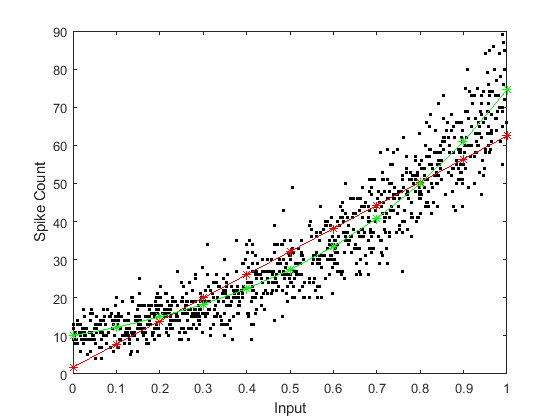

glmm = fitglme(T,'nrSpikes~visualInput','Distribution','Poisson','Link','Log');

testOutput = predict(glmm,testInput);
plot(testInput.visualInput,testOutput,'g*-')

Compare the AIC of the models:

glmm.ModelCriterion.AIC

ans = -453.4432

lmm.ModelCriterion.AIC

ans = 6.7812e+03

The `glmm` is much better in the AIC sense and the figure confirms this. Note that the linking funciton is` 'log'`. That means we are assuming there is stochastic process that generates a number of spikes with a Poisson distribution and that the log of the $\lambda$ parameter of that distribution (which determines both the mean and variance for a Poisson distribution) depend linearly on the input.


$$nrSpikes = Poisson(\lambda)

$$


and


$$log(\lambda) = \beta_0 + \beta_1*visualInput$$


which can be rewritten as:


$$\lambda = exp(\beta_0) * exp(\beta_1*visualInput)$$


The spike count model used above (`@response`) was, of course, constructed to match that assumption. This is another reminder that a statistical model is not just a trick to get a p-value; it is a model of the underlying mechanisms, and you have to make sure that the parameters and (for a generalized model) the linking function makes sense, so that the model describes parameters that are of real interest. 

If the mean does not increase exponentially with the input, you can chose a different linking function. This, however, can be tricky as you have to make sure that the linking function does not generate $\lambda
$ values that are impossible for a Poisson distribution. For instance, if you chose a linear linking funcion, then there are potential $\beta$ values for which $\lambda$ becomes negative, but a Poisson distribution cannot have a negative mean (because the values represent counts, which cannot be negative). 

You can address this by defining your own linking function. for instance, one that sets all values below zero to zero (so-called half-rectification). But because this linking function has a kink in it at 0, the `fitglme` algorithm can still get confused. Matlab will warn with messages stating that the estimation did not converge. Essentially, you want to make sure that the algorithm starts searching for values of the mean spike rate that are far away from the problematic zero. In the code below I achieve that by specifying '`muStart`' to a value in the middle of the range of observed spike counts. There may be better solutions to these kinds of modeling problems, but I have not found them yet. 

% Define a half-rectifier linking function
halfrectified.Link = @(x)((x>0).*x);
halfrectified.Inverse = @(x)((x>0).*x);
halfrectified.Derivative = @(x)(x>0);
halfrectified.SecondDerivative = @(x)(0);

% Create neuron where the mean rate depends linearly on the input
linearNeuron = @(input) (poissrnd(100*input));
nrTrials = 1000;
% Simulate responses
visualInput =  rand([nrTrials 1]); % Random visual inputs between 0 and 1
nrSpikes= linearNeuron(visualInput);
T= table(visualInput,nrSpikes);

% Fit a glmme using this linking function
glmm = fitglme(T,'nrSpikes~visualInput','Distribution','Poisson','Link',halfrectified,'muStart',mean(nrSpikes)*ones(nrTrials,1));

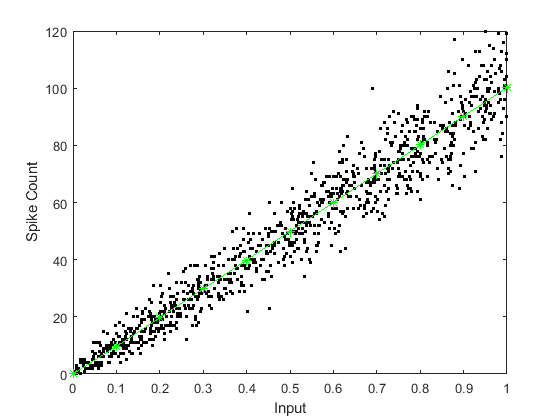


% Show the result
figure;clf;
plot(T.visualInput,T.nrSpikes,'.k');
hold on
xlabel 'Input'
ylabel 'Spike Count'

testOutput = predict(glmm,testInput);
plot(testInput.visualInput,testOutput,'g*-')

### Reaction Times and Inverse-Gaussian or Gamma Distributions

Let's look at another example where we combine theory with empirical observation to guide our modeling choices. We already know that reaction times are not normally distributed. In fact, we discussed that RT often follow an Ex-Gaussian distribution. Sadly, we cannot simply use the Ex-Gaussian in a generalized linear model (because it has 3 free parameters), so let's consider other distributions that may be better than the normal distribution for the analysis of reaction times.

One theory about reaction times states that they are the consequence of a sequence of processing steps, in which each step has a duration that is drawn from an exponential distrubition. If this model is correct, then it can be shown that observed reaction times should follow a gamma distribution.

Another theoretical view casts reaction times as the consequence of a decision making process called "diffusion to bound". Imagine that you are tasked with detecting some auditory beep from a background of a lot of white noise. Each time, something beep-like is detected by the auditory system, the evidence in favor of "beep" increases a bit (you can think of this as neural activity, maybe in some auditory neuron), but due to the noisy integration process, the evidence level wanders up and down ("diffuses"). The diffusion to bound model states that you hit the "yes" button as soon as the evidence level reaches some specific level  (i.e. the auditory neuron reaches a set level of activity and then triggers the motor response). If this is the underlying decision making process, then the reaction times will follow a so-called inverse-Gaussian distribution. 

The main feature of RT's that both these distributions capture is that they have a sharp rise (for short RT), followed by a long tail. For instance: 

rng(12345,'twister')
gamma = makedist('gamma','a',20,'b',14);
invGauss = makedist('InverseGaussian','mu',285,'lambda',6000);
rt = 0:750;
figure;
clf
plot(rt,gamma.pdf(rt));
hold on
plot(rt,invGauss.pdf(rt));
legend('Gamma','Inverse-Gaussian')
xlabel 'Reaction Time (ms)'
ylabel 'Probaility'

The two distributions are subtly different from each other , but a Gaussian with the same mean and standard deviation is different, especially in the tails of the distribution: 

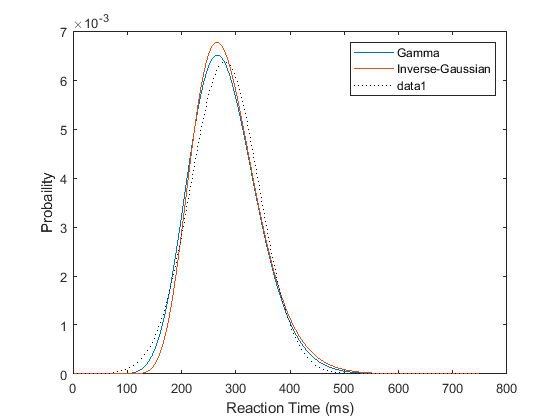

norm =makedist('normal','mu',mean(gamma),'sigma',std(gamma));
plot(rt,norm.pdf(rt),'k:')

The good news is that both the Gamma and the Inverse-Gaussian *can* be used in generalized linear models.  Let's return to the RT example in section 3

rng(12345,'twister'); 
mu = 230;
rt = 0:750;
TMSEFFECT = 20;
nrSubjects = 150;
% Generate fake data
shamRT = gamrnd(mu,1,nrSubjects,1); 
stimRT = gamrnd(mu-TMSEFFECT,1,nrSubjects,1);
hasTMS = [false(nrSubjects,1);true(nrSubjects,1)];
T= table([shamRT;stimRT],hasTMS, 'VariableNames',{'rt','TMS'});

% Fit using GLM
glmmGamma = fitglme(T,'rt~TMS','Distribution','Gamma','Link','Identity');

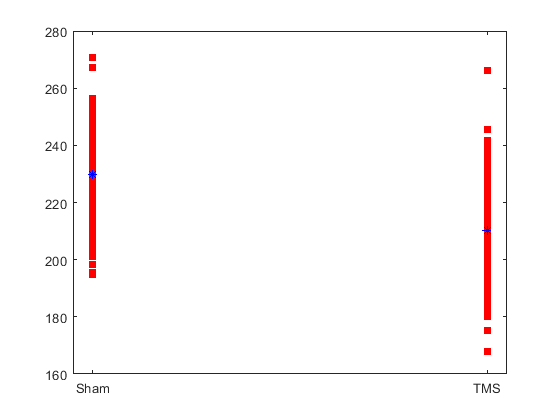


% Predictions
testInput = table([false;true],'VariableNames',{'TMS'});
meanResponse = predict(glmmGamma,testInput);

figure;
clf;
gscatter(double(T.TMS),T.rt);
hold on
plot([0;1],meanResponse,'b*')
set(gca,'XTick',[0 1],'XTickLabel',{'Sham','TMS'})

Note that the `fitglme` function complained about our choice of linking function. The reason is that Gamma distributed variables are only defined for values larger than zero, but our linking function  (the identity:` y=x`) allows any kind of value. You should not ignore these warnings. In this case, however, we know that the mean RT is much larger than zero, so there is no real concern that the model would generated reaction times that are negative (or even close to zero). As long as you are confident that the >0 constraint is not violated in practice, you can ignore the warning that Matlab issues (which only signals the *potential *for trouble).